try
pkg load signal;
end

global path
global base
global energy_dispersion
global data_dict
data_dict = struct([]);
path = '/sls/X03MA/data/x03maop/Data1/RIXS/Pisani_EPFL/RIXS/';
base = 'O';
energy_dispersion = 0.004359;

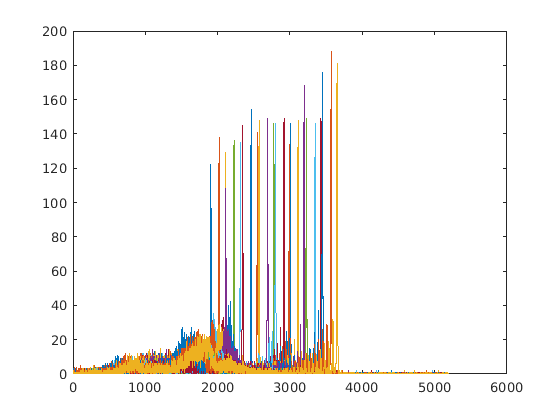

data = load_rixs([143:1:150]);
for i = 1:size(data,1)
plot(data(i,:));
hold on;
end
hold off;

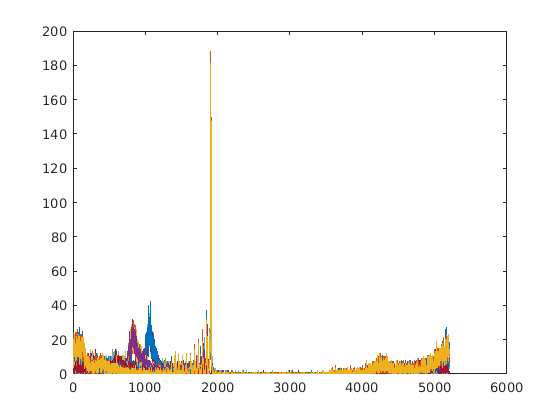

data = correlate_rixs(data,[0,6000]);
for i = 1:size(data,1)
plot(data(i,:));
hold on;
end
%xlim([1000,4000])
hold off;

sumdata = data(1,:);
for i = 2:size(data,1)
sumdata = sumdata + data(i,:);
end
plot(sumdata)

[x,y] = zero_energy(sumdata,1905);
plot(x,y)